# Classificació

## Netejar l'entorn

clc
close all
clear variables

## Parameters

% Scene settings
scenePath = 'imatges/DemoPratFullAlt.png';

% Sample settings
%samplePath = 'imatges/DemoPratFullAltMicro.png';
samplePath = 'imatges/DemoPratFullGreenPatch1.png';
sampleRot = 1; % Number of 90º rotations to additionally compute (0 - 3)

% Co-matrix settings
cmDist = 1;
cmDir = [0 1; 1 0; 1 1; -1 1];
cmSym = false; % Symmetric (offsets [1 0] == [-1 0])
cmProps = {"Contrast", "Correlation", "Energy", "Homogeneity"};

% Sliding Window settings
swStep = 10;

% Classification settings
nbest = 0; % Show best nbest cases. If 0, show cases better than threshold.
thr = 0.75;

% Presentation settings
maskAlpha = 0.65;

## Processem la mostra

sampleImg = imread(samplePath);
sampleImgGs = im2gray(sampleImg);

%figure
%montage({sampleImg, sampleImgGs}), title('Original and grayscaled sample');

sampleProps = NaN(size(cmProps, 2), size(cmDir, 1), sampleRot + 1);
for rot = 1:(sampleRot+1)

    sampleImgGsRot = rot90(sampleImgGs, rot-1);
    sampleProps(:, :, rot) = extractFeaturesGLCM(sampleImgGsRot, cmDir*cmDist, cmSym, cmProps);

end

## Propietats de la mostra

## Processem l'escena

sceneImg = imread(scenePath);
sceneImgGs = im2gray(sceneImg);

## Busquem coincidencies

swSize = size(sampleImgGs); % Sliding window must match sample size
sceneSize = size(sceneImgGs);

swNumY = floor( (sceneSize(1)-swSize(1)) / swStep );
swOffsetsY = swStep*(1:swNumY);

swNumX = floor( (sceneSize(2)-swSize(2)) / swStep );
swOffsetsX = swStep*(1:swNumX);

sampleCases = size(sampleProps, 3);

%tic
err = NaN(swNumY, swNumX, sampleCases);
parfor ny = 1:swNumY
    for nx = 1:swNumX

        y = swOffsetsY(ny);
        x = swOffsetsX(nx);

        swSample = sceneImgGs(y:(y+swSize(1)-1), x:(x+swSize(2)-1));
        swProps = extractFeaturesGLCM(swSample, cmDir*cmDist, cmSym, cmProps);

        for sc = 1:sampleCases
            err(ny, nx, sc) = sum( abs(sampleProps(:,:,sc) - swProps), 'all');
        end

    end
end
%toc

## Find matching cases

if nbest ~= 0
    bestThr = sort(err(:));
    thr = bestThr(nbest);
end

fprintf('Found %i cases for threshold %.4f', sum(err(:) <= thr), thr)

Found 185 cases for threshold 0.7500


%tic
mask = false(sceneSize(1), sceneSize(2), sampleCases);
for ny = 1:swNumY
    for nx = 1:swNumX
        for sc = 1:sampleCases
            if err(ny, nx, sc) <= thr
    
                y = swOffsetsY(ny);
                x = swOffsetsX(nx);
    
                mask(y:(y+swSize(1)-1), x:(x+swSize(2)-1), sc) = 1;
    
            end
        end
    end
end
%toc

mask = sum(mask,3);
fprintf('Maximum detection depth is %i', max(mask(:)))

Maximum detection depth is 2

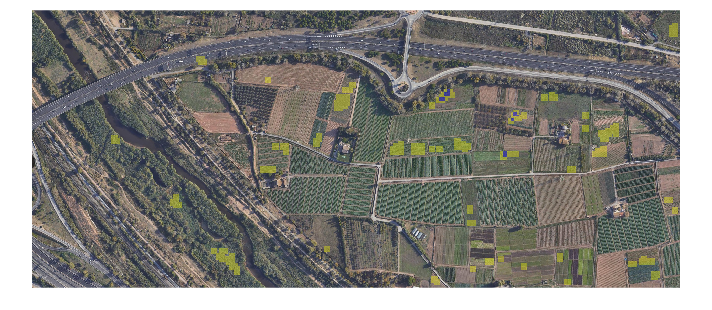


figure,
imshow( labeloverlay(sceneImg, mask, Transparency = maskAlpha));